# Solución de la cinemática inversa de un robot PUMA 560

## Resumen

Se presenta el desarrollo del modelo PUMA 560, desarrollado en el libro de "Introduction of the Robotics" de John Craig. Se presenta el modelado cinemátimatico de la posición mediante el método de Denavit-Hantemberg y el modelo cinemático inverso de la postura del robot, con el fin de generar la simulación de seguimiento de trayectoria.

## Definición de las funciones para el planteamiento del modelo

Definición de la matriz de transformación para el método de D-H

syms T_i_j(alpha_i,a_i,d_j,theta_j)

T_i_j(alpha_i,a_i,d_j,theta_j) = [cos(theta_j),-sin(theta_j),0,a_i;sin(theta_j)*cos(alpha_i),cos(theta_j)*cos(alpha_i),-sin(alpha_i),-d_j*sin(alpha_i);sin(theta_j)*sin(alpha_i),cos(theta_j)*sin(alpha_i),cos(alpha_i),d_j*cos(alpha_i);0,0,0,1]

$$T\_i\_j(alpha\_i, a\_i, d\_j, theta\_j) = \left(\begin{array}{cccc} \cos\left(\theta_{j}\right) & -\sin\left(\theta_{j}\right) & 0 & a_{i}\\ \cos\left(\alpha_{i}\right)\,\sin\left(\theta_{j}\right) & \cos\left(\alpha_{i}\right)\,\cos\left(\theta_{j}\right) & -\sin\left(\alpha_{i}\right) & -d_{j}\,\sin\left(\alpha_{i}\right)\\ \sin\left(\alpha_{i}\right)\,\sin\left(\theta_{j}\right) & \sin\left(\alpha_{i}\right)\,\cos\left(\theta_{j}\right) & \cos\left(\alpha_{i}\right) & d_{j}\,\cos\left(\alpha_{i}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Modelo cinemático de la posición

Para el modelo cinemático de la posición se definen de la siguiente manera los parámetros del método de Denavit-Hantemberg:

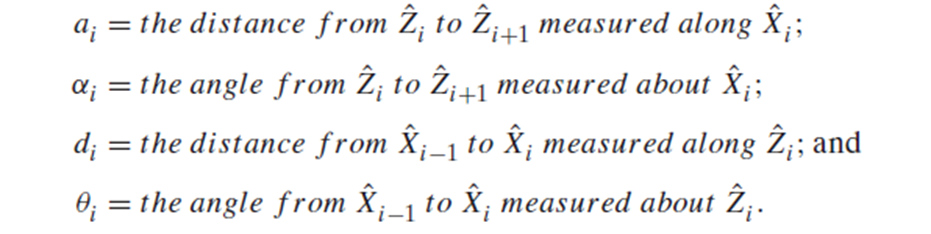

Con base en las definiciones anteriores se definen los siguientes sistemas de referencia para modelar el robot PUMA 560

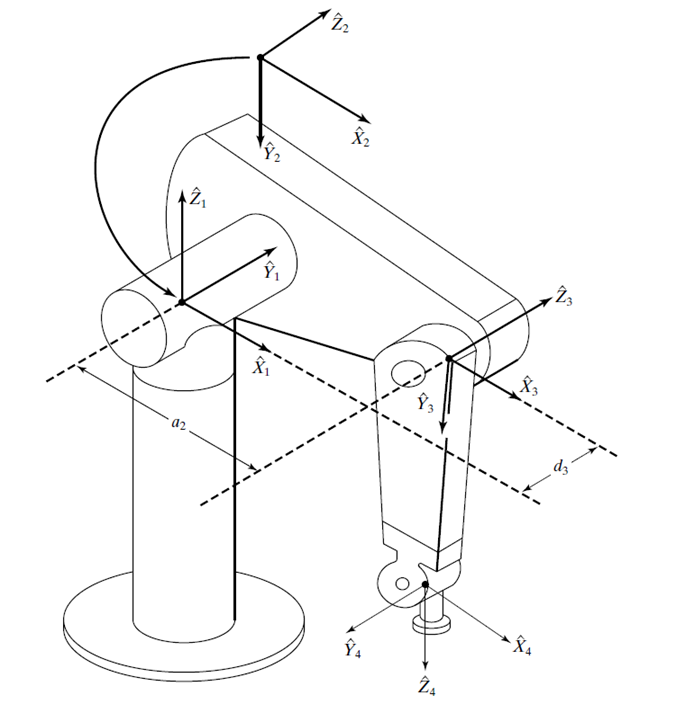

SSS

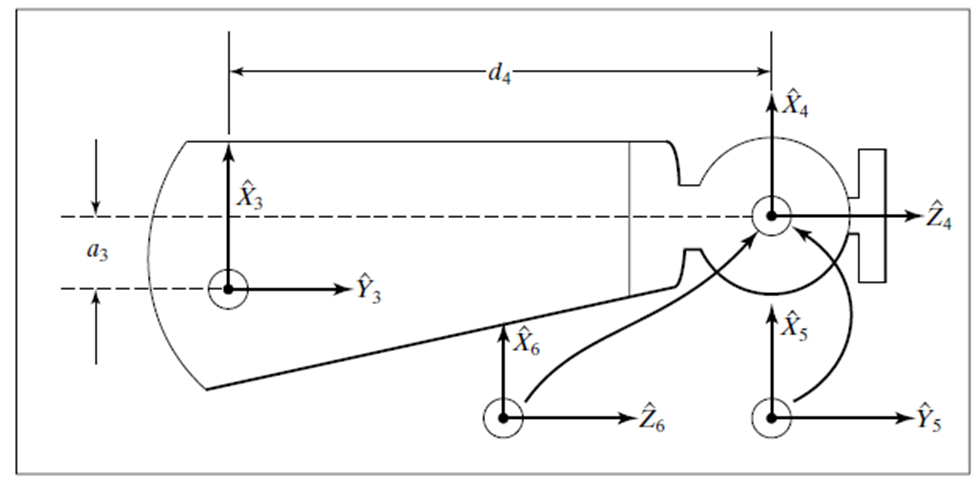

Planteamiento de los tres últimos grados de libertad para el robot

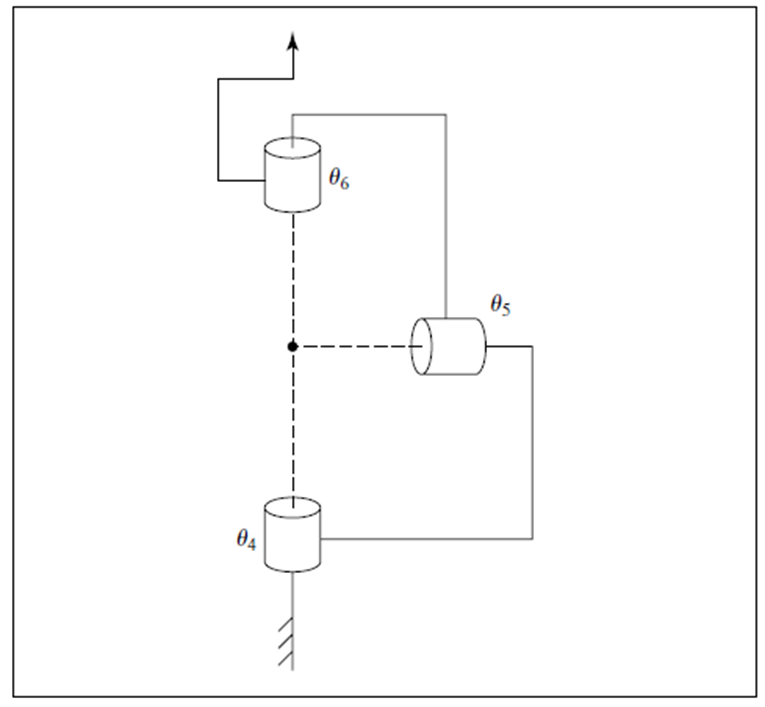

Con base en los parametros anteriores se establece la siguiente tabla:

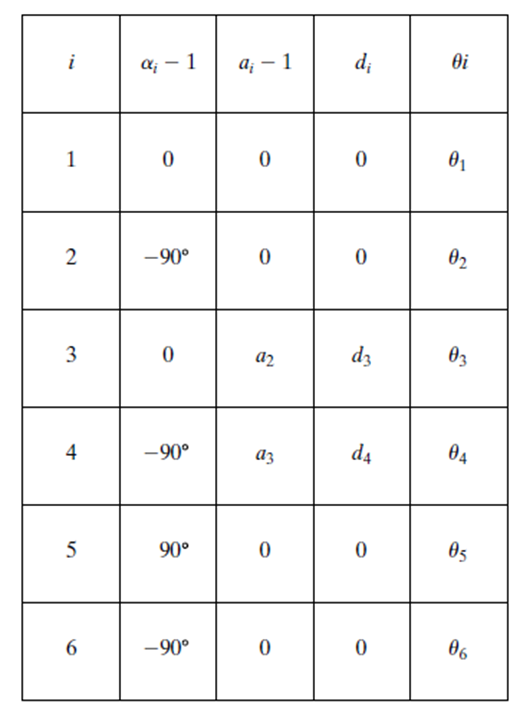

## Cálculo de las transformaciones

syms T_0_1 T_1_2 T_2_3 T_3_4 T_4_5 T_5_6 theta_1 theta_2 a_2 d_3 theta_3 a_3 d_4 theta_4 theta_5 theta_6

T_0_1 = T_i_j(0,0,0,theta_1)

$$T\_0\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_1_2 = T_i_j(-pi/2,0,0,theta_2)

$$T\_1\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ -\sin\left(\theta_{2}\right) & -\cos\left(\theta_{2}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_2_3 = T_i_j(0,a_2,d_3,theta_3)

$$T\_2\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & a_{2}\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & 0\\ 0 & 0 & 1 & d_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_3_4 = T_i_j(-pi/2,a_3,d_4,theta_4)

$$T\_3\_4 = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & -\sin\left(\theta_{4}\right) & 0 & a_{3}\\ 0 & 0 & 1 & d_{4}\\ -\sin\left(\theta_{4}\right) & -\cos\left(\theta_{4}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_4_5 = T_i_j(pi/2,0,0,theta_5)

$$T\_4\_5 = \left(\begin{array}{cccc} \cos\left(\theta_{5}\right) & -\sin\left(\theta_{5}\right) & 0 & 0\\ 0 & 0 & -1 & 0\\ \sin\left(\theta_{5}\right) & \cos\left(\theta_{5}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_5_6 = T_i_j(-pi/2,0,0,theta_6)

$$T\_5\_6 = \left(\begin{array}{cccc} \cos\left(\theta_{6}\right) & -\sin\left(\theta_{6}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ -\sin\left(\theta_{6}\right) & -\cos\left(\theta_{6}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Cálculando la transformación que describe la brida del efector final del robot:

syms T_0_6 T_0_3 

T_0_3 = simplify(T_0_1*T_1_2*T_2_3)

$$T\_0\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & a_{2}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-d_{3}\,\sin\left(\theta_{1}\right)\\ \cos\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & d_{3}\,\cos\left(\theta_{1}\right)+a_{2}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ -\sin\left(\theta_{2}+\theta_{3}\right) & -\cos\left(\theta_{2}+\theta_{3}\right) & 0 & -a_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T_3_6 = simplify(T_3_4*T_4_5*T_5_6)

$$T\_3\_6 = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\,\cos\left(\theta_{6}\right)-\sin\left(\theta_{4}\right)\,\sin\left(\theta_{6}\right) & -\cos\left(\theta_{6}\right)\,\sin\left(\theta_{4}\right)-\cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{6}\right) & -\cos\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right) & a_{3}\\ \cos\left(\theta_{6}\right)\,\sin\left(\theta_{5}\right) & -\sin\left(\theta_{5}\right)\,\sin\left(\theta_{6}\right) & \cos\left(\theta_{5}\right) & d_{4}\\ -\cos\left(\theta_{4}\right)\,\sin\left(\theta_{6}\right)-\cos\left(\theta_{5}\right)\,\cos\left(\theta_{6}\right)\,\sin\left(\theta_{4}\right) & \cos\left(\theta_{5}\right)\,\sin\left(\theta_{4}\right)\,\sin\left(\theta_{6}\right)-\cos\left(\theta_{4}\right)\,\cos\left(\theta_{6}\right) & \sin\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

simplify(T_0_3*T_3_6)


T_0_6 = collect(simplify(T_0_3*T_3_6),cos(theta_1))

%simplify(T_0_1*T_1_2*T_2_3*T_3_4*T_4_5*T_5_6)
T_0_1*T_1_2*T_2_3*T_3_4*T_4_5*T_5_6